clearvars; close all; clc;
set(0,"DefaultAxesFontSize",8);
xlimmf		= [2e1 2e4];
xtickmf		= [1e2 1e3 2e3];
xlimlf		= xlimmf;
xticklf		= [2e1 1e3 2e3];
ylimmf		= [80 115];
ylimlf		= ylimmf;
grcol		= [.75 .75 .75];

# MEH research

2025-10-01, JVsound

## Single MF or LF

### MF - No LF taps

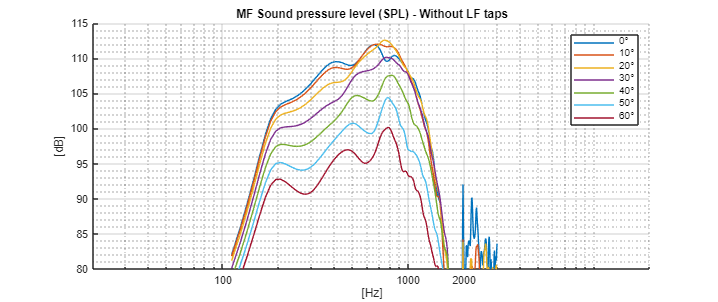

% Create sim objects
xdot		= 1e-3;
egmf		= 2;

mfp0		= buildacsimobj("mfp0",egmf,xdot);
mfp10		= buildacsimobj("mfp10",egmf,xdot);
mfp20		= buildacsimobj("mfp20",egmf,xdot);
mfp30		= buildacsimobj("mfp30",egmf,xdot);
mfp40		= buildacsimobj("mfp40",egmf,xdot);
mfp50		= buildacsimobj("mfp50",egmf,xdot);
mfp60		= buildacsimobj("mfp60",egmf,xdot);

mf15p0		= buildacsimobj("mf15p0",egmf,xdot);
mf15p10		= buildacsimobj("mf15p10",egmf,xdot);
mf15p20		= buildacsimobj("mf15p20",egmf,xdot);
mf15p30		= buildacsimobj("mf15p30",egmf,xdot);
mf15p40		= buildacsimobj("mf15p40",egmf,xdot);
mf15p50		= buildacsimobj("mf15p50",egmf,xdot);
mf15p60		= buildacsimobj("mf15p60",egmf,xdot);

% Figures:
fig1				= figure;
fig1.Position(3)	= 1000;
ax1					= axes(fig1); hold on; grid on; grid minor;
ax1.XScale			= "log";
ax1.XLim			= xlimmf;
ax1.XTick			= xtickmf;
ax1.YLim			= ylimmf;
ax1.Title.String	= "MF Sound pressure level (SPL) - Without LF taps";
ax1.XLabel.String	= "[Hz]";
ax1.YLabel.String	= "[dB]";


plot(ax1,mfp0.f,mfp0.spl);
plot(ax1,mfp10.f,mfp10.spl);
plot(ax1,mfp20.f,mfp20.spl);
plot(ax1,mfp30.f,mfp30.spl);
plot(ax1,mfp40.f,mfp40.spl);
plot(ax1,mfp50.f,mfp50.spl);
plot(ax1,mfp60.f,mfp60.spl);

ax1.ColorOrderIndex = 1;
% plot(ax1,mf15p0.f,mf15p0.spl,LineStyle="--");
% plot(ax1,mf15p10.f,mf15p10.spl,LineStyle="--");
% plot(ax1,mf15p20.f,mf15p20.spl,LineStyle="--");
% plot(ax1,mf15p30.f,mf15p30.spl,LineStyle="--");
% plot(ax1,mf15p40.f,mf15p40.spl,LineStyle="--");
% plot(ax1,mf15p50.f,mf15p50.spl,LineStyle="--");
% plot(ax1,mf15p60.f,mf15p60.spl,LineStyle="--");

leg1		= legend(ax1,"0\circ","10\circ","20\circ","30\circ","40\circ","50\circ","60\circ");

### LF - No MF taps

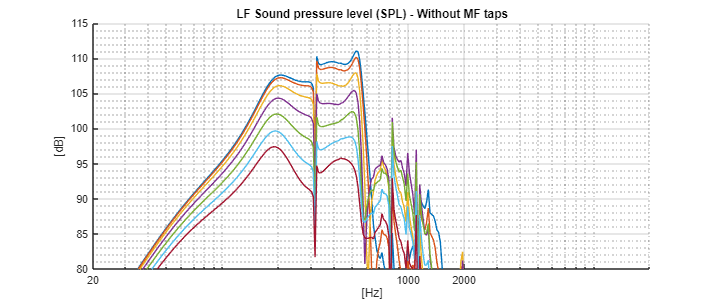

% Create sim objects
eglf		= 2;

lfp0		= buildacsimobj("lfp0",eglf,xdot);
lfp10		= buildacsimobj("lfp10",eglf,xdot);
lfp20		= buildacsimobj("lfp20",eglf,xdot);
lfp30		= buildacsimobj("lfp30",eglf,xdot);
lfp40		= buildacsimobj("lfp40",eglf,xdot);
lfp50		= buildacsimobj("lfp50",eglf,xdot);
lfp60		= buildacsimobj("lfp60",eglf,xdot);

% Figures:
fig3				= figure;
fig3.Position(3)	= 1000;
ax3					= axes(fig3); hold on; grid on; grid minor;
ax3.XScale			= "log";
ax3.XLim			= xlimlf;
ax3.XTick			= xticklf;
ax3.YLim			= ylimlf;
ax3.Title.String	= "LF Sound pressure level (SPL) - Without MF taps";
ax3.XLabel.String	= "[Hz]";
ax3.YLabel.String	= "[dB]";

plot(ax3,lfp0.f,lfp0.spl);
plot(ax3,lfp10.f,lfp10.spl);
plot(ax3,lfp20.f,lfp20.spl);
plot(ax3,lfp30.f,lfp30.spl);
plot(ax3,lfp40.f,lfp40.spl);
plot(ax3,lfp50.f,lfp50.spl);
plot(ax3,lfp60.f,lfp60.spl);

## Adding central LF tap

1 central tap, with an area 1/10th of the diaphragm area.

% Sd area of 12" driver:
Sd			= 2 * 265.46*1e-4;

% Tap area:
ta			= Sd / 10;

% Tap dia [mm]:
td			= sqrt(ta * 4 / pi) * 1e3

td = 82.2185

### MF

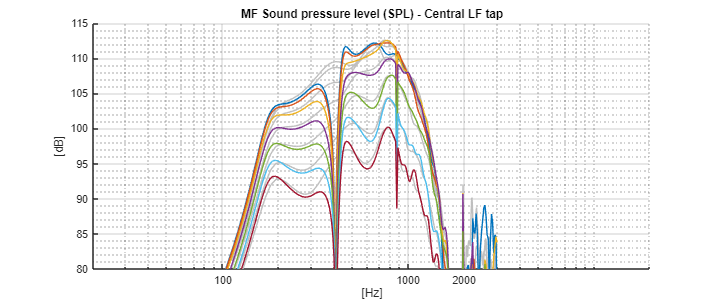

% Create sim objects
mfctlfp0		= buildacsimobj("mfctlfp0",egmf,xdot);
mfctlfp10		= buildacsimobj("mfctlfp10",egmf,xdot);
mfctlfp20		= buildacsimobj("mfctlfp20",egmf,xdot);
mfctlfp30		= buildacsimobj("mfctlfp30",egmf,xdot);
mfctlfp40		= buildacsimobj("mfctlfp40",egmf,xdot);
mfctlfp50		= buildacsimobj("mfctlfp50",egmf,xdot);
mfctlfp60		= buildacsimobj("mfctlfp60",egmf,xdot);

% Figures:
fig3		= figure;
fig3.Position(3)	= 1000;
ax3			= axes(fig3); hold on; grid on; grid minor;
ax3.XScale	= "log";
ax3.XLim	= xlimmf;
ax3.XTick	= xtickmf;
ax3.YLim	= ylimmf;
ax3.Title.String	= "MF Sound pressure level (SPL) - Central LF tap";
ax3.XLabel.String	= "[Hz]";
ax3.YLabel.String	= "[dB]";

plot(ax3,mfp0.f,mfp0.spl,Color=grcol);
plot(ax3,mfp10.f,mfp10.spl,Color=grcol);
plot(ax3,mfp20.f,mfp20.spl,Color=grcol);
plot(ax3,mfp30.f,mfp30.spl,Color=grcol);
plot(ax3,mfp40.f,mfp40.spl,Color=grcol);
plot(ax3,mfp50.f,mfp50.spl,Color=grcol);
plot(ax3,mfp60.f,mfp60.spl,Color=grcol);

ax3.ColorOrderIndex = 1;
plot(ax3,mfctlfp0.f,mfctlfp0.spl);
plot(ax3,mfctlfp10.f,mfctlfp10.spl);
plot(ax3,mfctlfp20.f,mfctlfp20.spl);
plot(ax3,mfctlfp30.f,mfctlfp30.spl);
plot(ax3,mfctlfp40.f,mfctlfp40.spl);
plot(ax3,mfctlfp50.f,mfctlfp50.spl);
plot(ax3,mfctlfp60.f,mfctlfp60.spl);

### LF

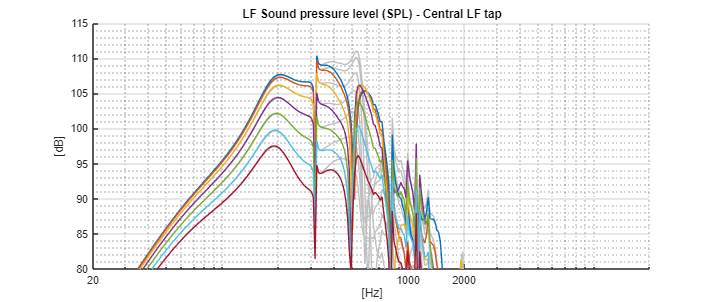

% Create sim objects
lfctlfp0		= buildacsimobj("lfctlfp0",eglf,xdot);
lfctlfp10		= buildacsimobj("lfctlfp10",eglf,xdot);
lfctlfp20		= buildacsimobj("lfctlfp20",eglf,xdot);
lfctlfp30		= buildacsimobj("lfctlfp30",eglf,xdot);
lfctlfp40		= buildacsimobj("lfctlfp40",eglf,xdot);
lfctlfp50		= buildacsimobj("lfctlfp50",eglf,xdot);
lfctlfp60		= buildacsimobj("lfctlfp60",eglf,xdot);

% Figures:
fig6		= figure;
fig6.Position(3)	= 1000;
ax6			= axes(fig6); hold on; grid on; grid minor;
ax6.XScale	= "log";
ax6.XLim	= xlimlf;
ax6.XTick	= xticklf;
ax6.YLim	= ylimlf;
ax6.Title.String	= "LF Sound pressure level (SPL) - Central LF tap";
ax6.XLabel.String	= "[Hz]";
ax6.YLabel.String	= "[dB]";

plot(ax6,lfp0.f,lfp0.spl,Color=grcol);
plot(ax6,lfp10.f,lfp10.spl,Color=grcol);
plot(ax6,lfp20.f,lfp20.spl,Color=grcol);
plot(ax6,lfp30.f,lfp30.spl,Color=grcol);
plot(ax6,lfp40.f,lfp40.spl,Color=grcol);
plot(ax6,lfp50.f,lfp50.spl,Color=grcol);
plot(ax6,lfp60.f,lfp60.spl,Color=grcol);

ax6.ColorOrderIndex = 1;
plot(ax6,lfctlfp0.f,lfctlfp0.spl);
plot(ax6,lfctlfp10.f,lfctlfp10.spl);
plot(ax6,lfctlfp20.f,lfctlfp20.spl);
plot(ax6,lfctlfp30.f,lfctlfp30.spl);
plot(ax6,lfctlfp40.f,lfctlfp40.spl);
plot(ax6,lfctlfp50.f,lfctlfp50.spl);
plot(ax6,lfctlfp60.f,lfctlfp60.spl);

## Add BR port

### MF

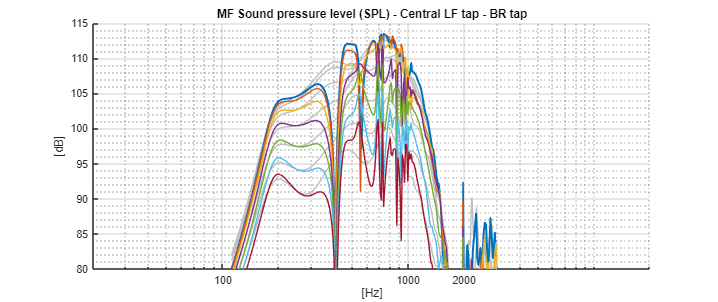

% Create sim objects
mfctlfbrp0		= buildacsimobj("mfctlfbrp0",egmf,xdot);
mfctlfbrp10		= buildacsimobj("mfctlfbrp10",egmf,xdot);
mfctlfbrp20		= buildacsimobj("mfctlfbrp20",egmf,xdot);
mfctlfbrp30		= buildacsimobj("mfctlfbrp30",egmf,xdot);
mfctlfbrp40		= buildacsimobj("mfctlfbrp40",egmf,xdot);
mfctlfbrp50		= buildacsimobj("mfctlfbrp50",egmf,xdot);
mfctlfbrp60		= buildacsimobj("mfctlfbrp60",egmf,xdot);

% Figures:
fig5		= figure;
fig5.Position(3)	= 1000;
ax5			= axes(fig5); hold on; grid on; grid minor;
ax5.XScale	= "log";
ax5.XLim	= xlimmf;
ax5.XTick	= xtickmf;
ax5.YLim	= ylimmf;
ax5.Title.String	= "MF Sound pressure level (SPL) - Central LF tap - BR tap";
ax5.XLabel.String	= "[Hz]";
ax5.YLabel.String	= "[dB]";

plot(ax5,mfp0.f,mfp0.spl,Color=grcol);
plot(ax5,mfp10.f,mfp10.spl,Color=grcol);
plot(ax5,mfp20.f,mfp20.spl,Color=grcol);
plot(ax5,mfp30.f,mfp30.spl,Color=grcol);
plot(ax5,mfp40.f,mfp40.spl,Color=grcol);
plot(ax5,mfp50.f,mfp50.spl,Color=grcol);
plot(ax5,mfp60.f,mfp60.spl,Color=grcol);

ax5.ColorOrderIndex = 1;
plot(ax5,mfctlfbrp0.f,mfctlfbrp0.spl,LineWidth=1.5);
plot(ax5,mfctlfbrp10.f,mfctlfbrp10.spl);
plot(ax5,mfctlfbrp20.f,mfctlfbrp20.spl);
plot(ax5,mfctlfbrp30.f,mfctlfbrp30.spl);
plot(ax5,mfctlfbrp40.f,mfctlfbrp40.spl);
plot(ax5,mfctlfbrp50.f,mfctlfbrp50.spl);
plot(ax5,mfctlfbrp60.f,mfctlfbrp60.spl);


f		= mfctlfbrp30.f';
spl		= mfctlfbrp30.spl';

n		= 5;             % Number of elements to create the mean over
s1		= size(spl,1);      % Find the next smaller multiple of n
m		= s1 - mod(s1, n);
y		= reshape(spl(1:m),n,[]);     % Reshape x to a [n, m/n] matrix
f2		= reshape(f(1:m),n,[]);
splav	= transpose(sum(y, 1)/n);  % Calculate the mean over the 1st dim
fav		= transpose(sum(f2,1)/n);

% plot(ax5,fav,splav,LineWidth=1.5)

### LF

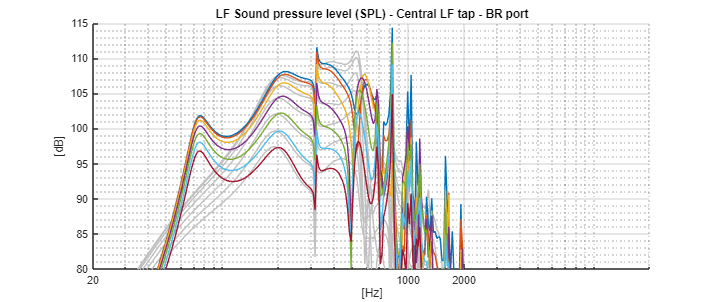

lfctlfbrp0		= buildacsimobj("lfctlfbrp0",eglf,xdot);
lfctlfbrp10		= buildacsimobj("lfctlfbrp10",eglf,xdot);
lfctlfbrp20		= buildacsimobj("lfctlfbrp20",eglf,xdot);
lfctlfbrp30		= buildacsimobj("lfctlfbrp30",eglf,xdot);
lfctlfbrp40		= buildacsimobj("lfctlfbrp40",eglf,xdot);
lfctlfbrp50		= buildacsimobj("lfctlfbrp50",eglf,xdot);
lfctlfbrp60		= buildacsimobj("lfctlfbrp60",eglf,xdot);

% Figures:
fig4		= figure;
fig4.Position(3)	= 1000;
ax4			= axes(fig4); hold on; grid on; grid minor;
ax4.XScale	= "log";
ax4.XLim	= xlimlf;
ax4.XTick	= xticklf;
ax4.YLim	= ylimlf;
ax4.Title.String	= "LF Sound pressure level (SPL) - Central LF tap - BR port";
ax4.XLabel.String	= "[Hz]";
ax4.YLabel.String	= "[dB]";

plot(ax4,lfp0.f,lfp0.spl,Color=grcol);
plot(ax4,lfp10.f,lfp10.spl,Color=grcol);
plot(ax4,lfp20.f,lfp20.spl,Color=grcol);
plot(ax4,lfp30.f,lfp30.spl,Color=grcol);
plot(ax4,lfp40.f,lfp40.spl,Color=grcol);
plot(ax4,lfp50.f,lfp50.spl,Color=grcol);
plot(ax4,lfp60.f,lfp60.spl,Color=grcol);
ax4.ColorOrderIndex = 1;

plot(ax4,lfctlfbrp0.f,lfctlfbrp0.spl);
plot(ax4,lfctlfbrp10.f,lfctlfbrp10.spl);
plot(ax4,lfctlfbrp20.f,lfctlfbrp20.spl);
plot(ax4,lfctlfbrp30.f,lfctlfbrp30.spl);
plot(ax4,lfctlfbrp40.f,lfctlfbrp40.spl);
plot(ax4,lfctlfbrp50.f,lfctlfbrp50.spl);
plot(ax4,lfctlfbrp60.f,lfctlfbrp60.spl);